# Validate geodesics

Validate that the output of `quadric.geodesic` is close to that of `quadric.geodesicPanou` for those ellipsoidal locations that both routines can process.

When the spherical ametropia of the eye is less than –2 D, the dimension order of the ellipsoidal radii of the vitreous chamber switch (i.e., the eye becomes taller than is wide). By adjusting the assigned value for `sphericalAmetropia` between negative values (e.g., –5), positive values (+3) and zero, one can confirm that the approximation agrees with the boundary solution of Panou 2013 to substantial accuracy. For may pairs of points the Panou solution returns nan, as the geodesic crosses a pole or a sign reversal of the geodesic coordinates, causing the routine to fail. It is this inability to trace geodesics between all points that motivated the creation of the approximation approach in `quadric.geodesic`.

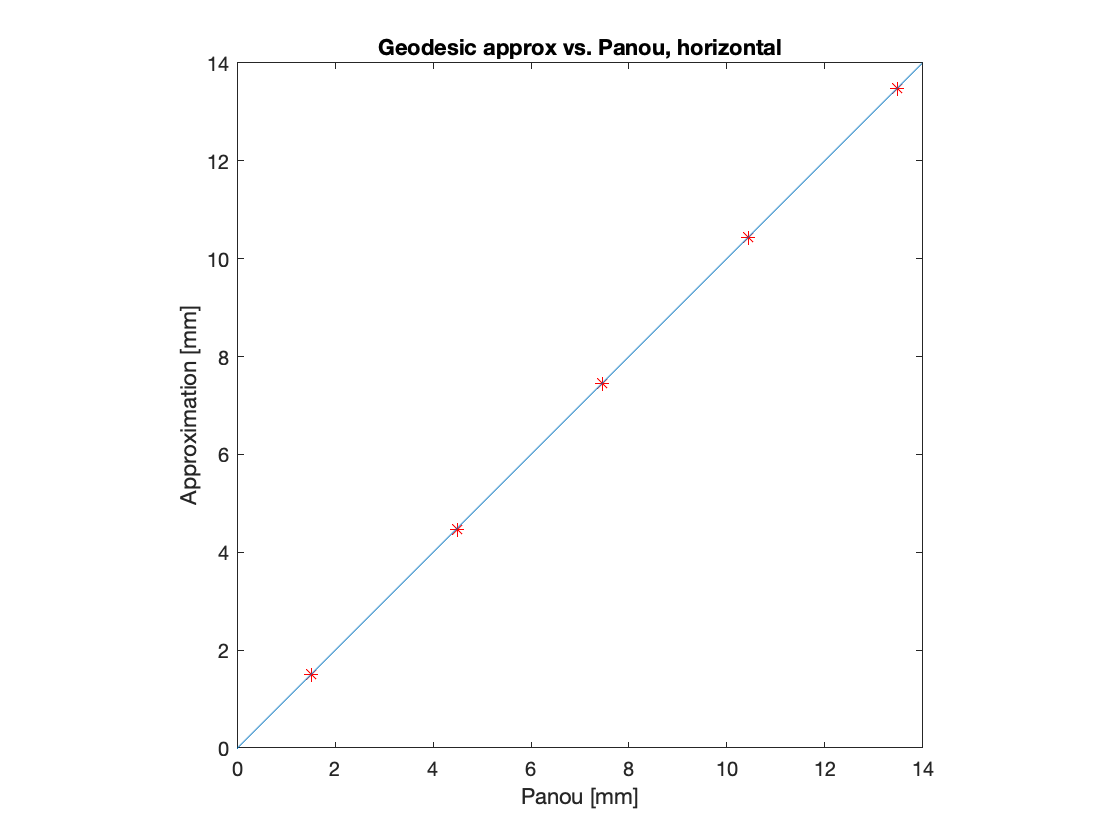

% Define the eye
sphericalAmetropia = -5; % Changes in this value will substantially alter the mapping
eye = modelEyeParameters('sphericalAmetropia',sphericalAmetropia);

% Define the positions that will be tested
hPos = -45:10:45;

% Extract some landmarks
angleReferenceCoord = eye.landmarks.incidentNode.coords;
distanceReferenceCoord = calcPrincipalPoint(eye);
rayOriginDistance = 1e4;

% The first point is at [-9 -9] degrees visual field, to get away from
% the vertex (where the Panou solution fails)
startField = [-9 -9];
rayPath = calcNodalRayFromField(eye,startField,rayOriginDistance,angleReferenceCoord,distanceReferenceCoord);
startCoord = rayPath(:,end);

% Loop over horizontal field positions
d = nan(size(hPos));
dPanou = nan(size(hPos));
for hh = 1:length(hPos)
    fieldPos = [hPos(hh) 0]+startField;
    rayPath = calcNodalRayFromField(eye,fieldPos,rayOriginDistance,angleReferenceCoord,distanceReferenceCoord);
    d(hh) = quadric.geodesic(eye.retina.S,[startCoord,rayPath(:,end)]);
    dPanou(hh) = quadric.geodesicPanou(eye.retina.S,[startCoord,rayPath(:,end)]);
end

% Plot
Hneg = hPos < 0;
figure
plot(abs(dPanou(Hneg)),d(Hneg),'*r')
hold on
plot(abs(dPanou(~Hneg)),d(~Hneg),'*b')
title('Geodesic approx vs. Panou, horizontal')
xlabel('Panou [mm]')
ylabel('Approximation [mm]')
axis square
refline(1,0)

Repeat for vertical positions

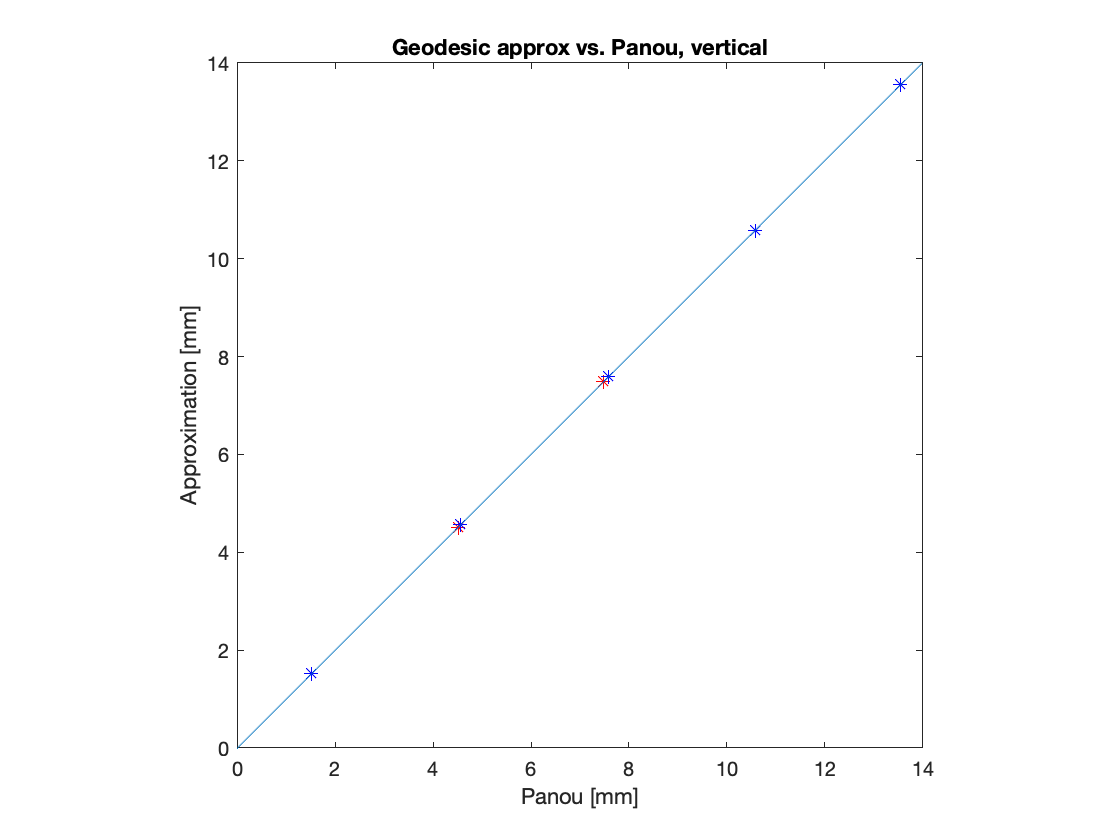

% Define the positions that will be tested
vPos = -45:10:45;

% Extract some landmarks
angleReferenceCoord = eye.landmarks.incidentNode.coords;
distanceReferenceCoord = calcPrincipalPoint(eye);
rayOriginDistance = 1e4;

% The first point is at [-9 -9] degrees visual field, to get away from
% the vertex (where the Panou solution fails)
startField = [-9 -9];
rayPath = calcNodalRayFromField(eye,startField,rayOriginDistance,angleReferenceCoord,distanceReferenceCoord);
startCoord = rayPath(:,end);

% Loop over vertical field positions
d = nan(size(vPos));
dPanou = nan(size(vPos));
for vv = 1:length(vPos)
    fieldPos = [0 vPos(vv)]+startField;
    rayPath = calcNodalRayFromField(eye,fieldPos,rayOriginDistance,angleReferenceCoord,distanceReferenceCoord);
    d(vv) = quadric.geodesic(eye.retina.S,[startCoord,rayPath(:,end)]);
    dPanou(vv) = quadric.geodesicPanou(eye.retina.S,[startCoord,rayPath(:,end)]);
end

% Plot
Vneg = vPos < 0;
figure
plot(abs(dPanou(Vneg)),d(Vneg),'*r')
hold on
plot(abs(dPanou(~Vneg)),d(~Vneg),'*b')
title('Geodesic approx vs. Panou, vertical')
xlabel('Panou [mm]')
ylabel('Approximation [mm]')
axis square
refline(1,0)